## Prova di trasferimento con orbita biellittica

Dati delle orbite iniziale e finale

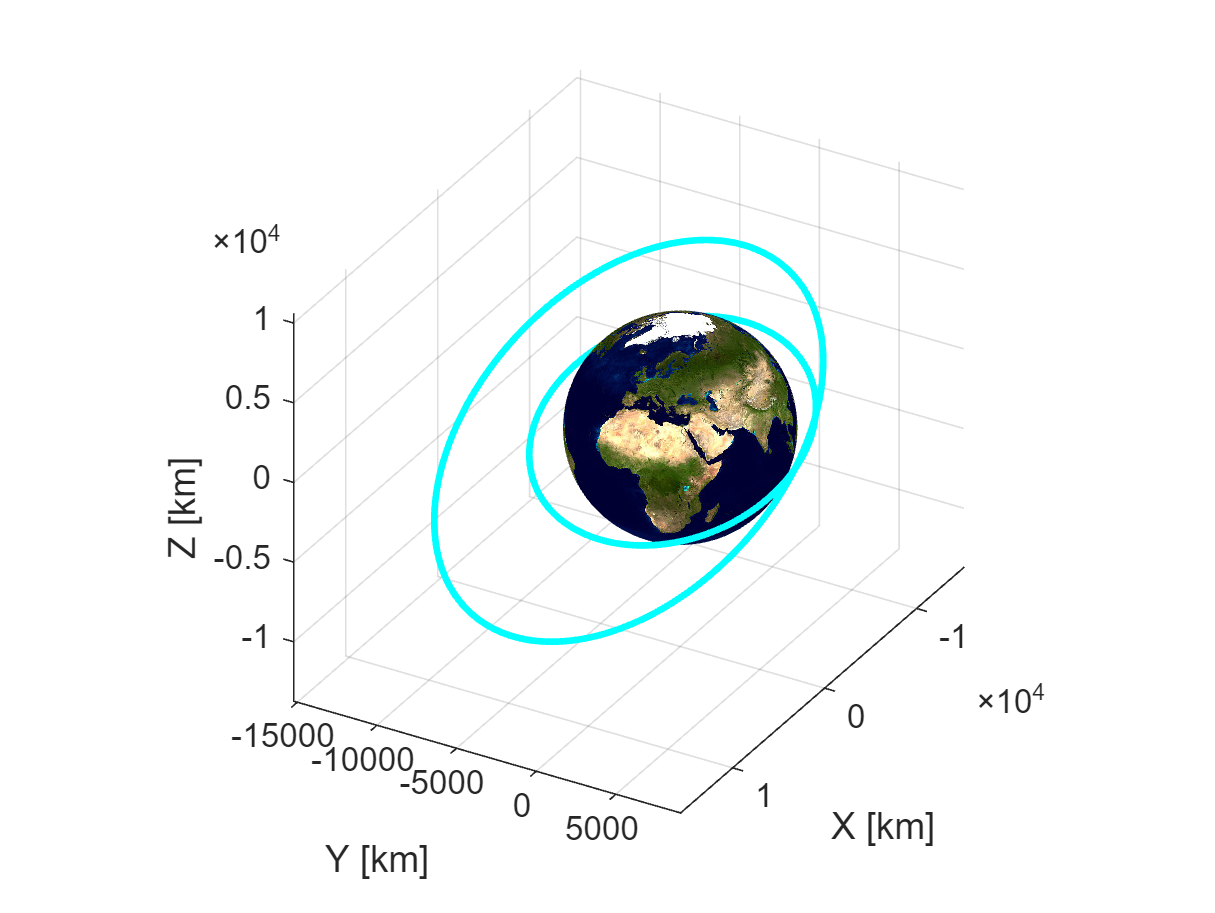

clear
close
clc

comet = false;
mu = 398600; 
dth = 1*pi/180;
% Dati orbita iniziale
rr = [-4350.9803; -6668.1393; 1517.6565];
vv = [4.9690; -4.2630; -2.4370];

[ai , ei, inci, OMi, omi, thi] = car2par(rr, vv, mu);

Terra_3D
plotOrbit_new(ai, ei, inci, OMi, omi, thi, thi+2*pi, dth, mu)
current_axes = gca;

% Dati orbita finale
af = 12950.0; 
ef = 0.2682; 
incf = 0.7222; 
OMf = 1.0360;
omf = 0.7604; 
thf = 1.6230;
plotOrbit_new(af, ef, incf, OMf, omf, thf, thf+2*pi, dth, mu, current_axes)

### Trasferimento biellittico con cambio di piano

Per un trasferimento biellittico, è necessario scegliere un raggio di apogeo delle ellissi di trasferimento. In un primo momento, sceglieremo arbitrariamente un raggio uguale a tre volte il semiasse maggiore dell'ellisse finale.

ra_t_v = 1.1*af:500:1.5*af

ra_t_v = 1.0e+04 *

    1.4245    1.4745    1.5245    1.5745    1.6245    1.6745    1.7245    1.7745    1.8245    1.8745    1.9245


ra_t = ra_t_v(5);

Poi calcoliamo semiasse maggiore, raggio del pericentro ed eccentricità della prima ellisse di trasferimento.

% Dati prima orbita di trasferimento
rpi = ai*(1-ei); 
at1 = (ra_t + rpi)/2;
et1 = (at1-rpi)/at1;

Calcoliamo il DeltaV della prima manovra.

DeltaV1 = sqrt(mu)*(sqrt((2/rpi)-(1/at1)) - sqrt(((2/rpi)-(1/ai))));

Utilizziamo la funzione changeOrbitalPlane per trovare i punti in cui è possibile effettuare il cambio di piano. Di default, la funzione ritorna il punto (theta) dove è più conveniente effettuare la manovra in termini di DeltaV.

[DeltaV_plane, omf_in, possible_theta] = changeOrbitalPlane(at1, et1, inci, OMi, omi, incf, OMf, mu);

Calcoliamo semiasse maggiore, raggio del pericentro ed eccentricità della prima ellisse di trasferimento.

% Dati seconda orbita di trasferimento
rpf = af*(1-ef);
at2 = (ra_t + rpf)/2;
et2 = (at2-rpf)/at2;

Calcoliamo il DeltaV della seconda e terza manovra.

DeltaV2 = sqrt(mu)*(sqrt((2/ra_t)-(1/at2)) - sqrt(((2/ra_t)-(1/at1))));
DeltaV3 = sqrt(mu)*(sqrt((2/rpf)-(1/af)) - sqrt(((2/rpf)-(1/at2))));

Disegniamo le orbite di trasferimento.

Questo blocco disegna la prima ellisse di trasferimento, sino al punto del cambio di piano. Poi disegna l'ellisse con la nuova inclinazione.

current_axes = axes()

current_axes =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


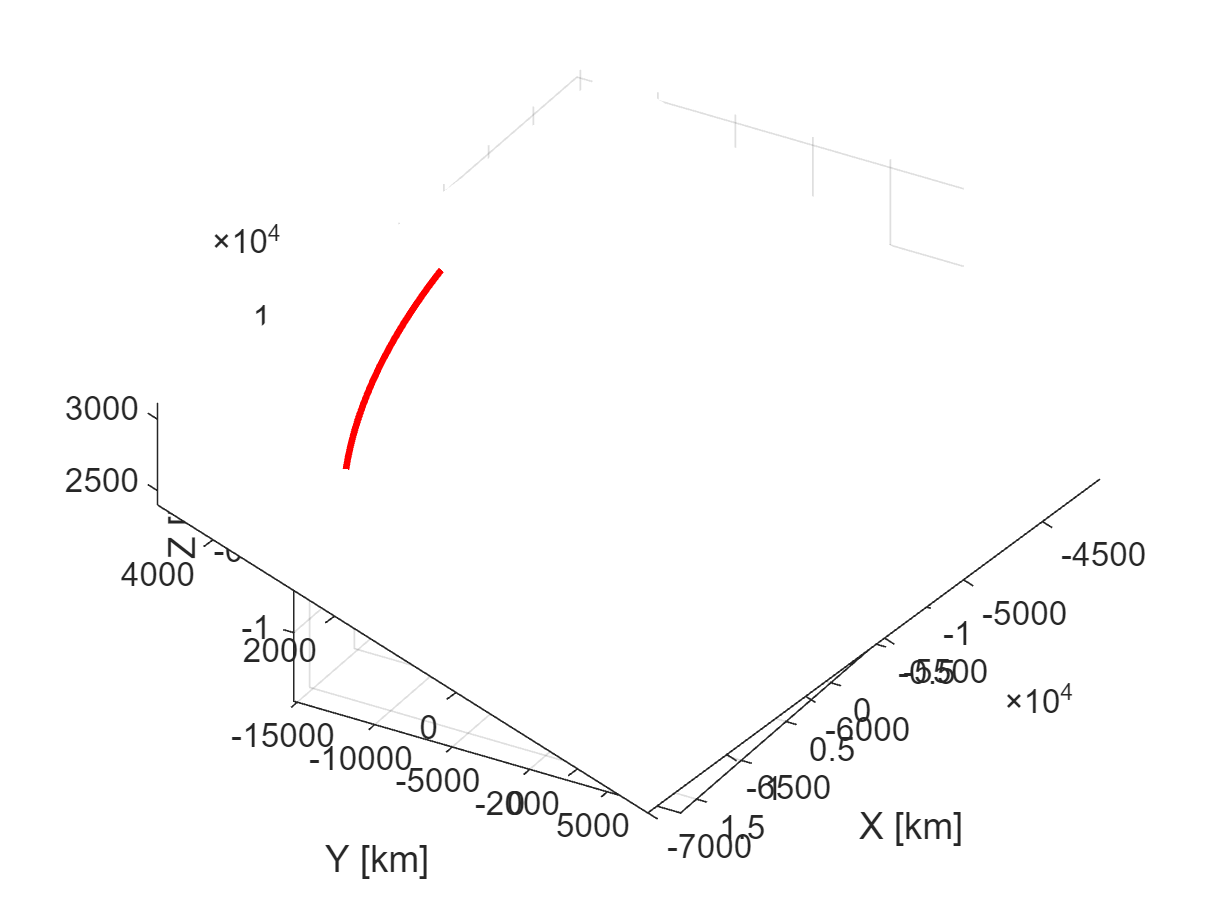

plotOrbit_new(at1, et1, inci, OMi, omi, 0, possible_theta(1), dth, mu, current_axes, comet, 'r')

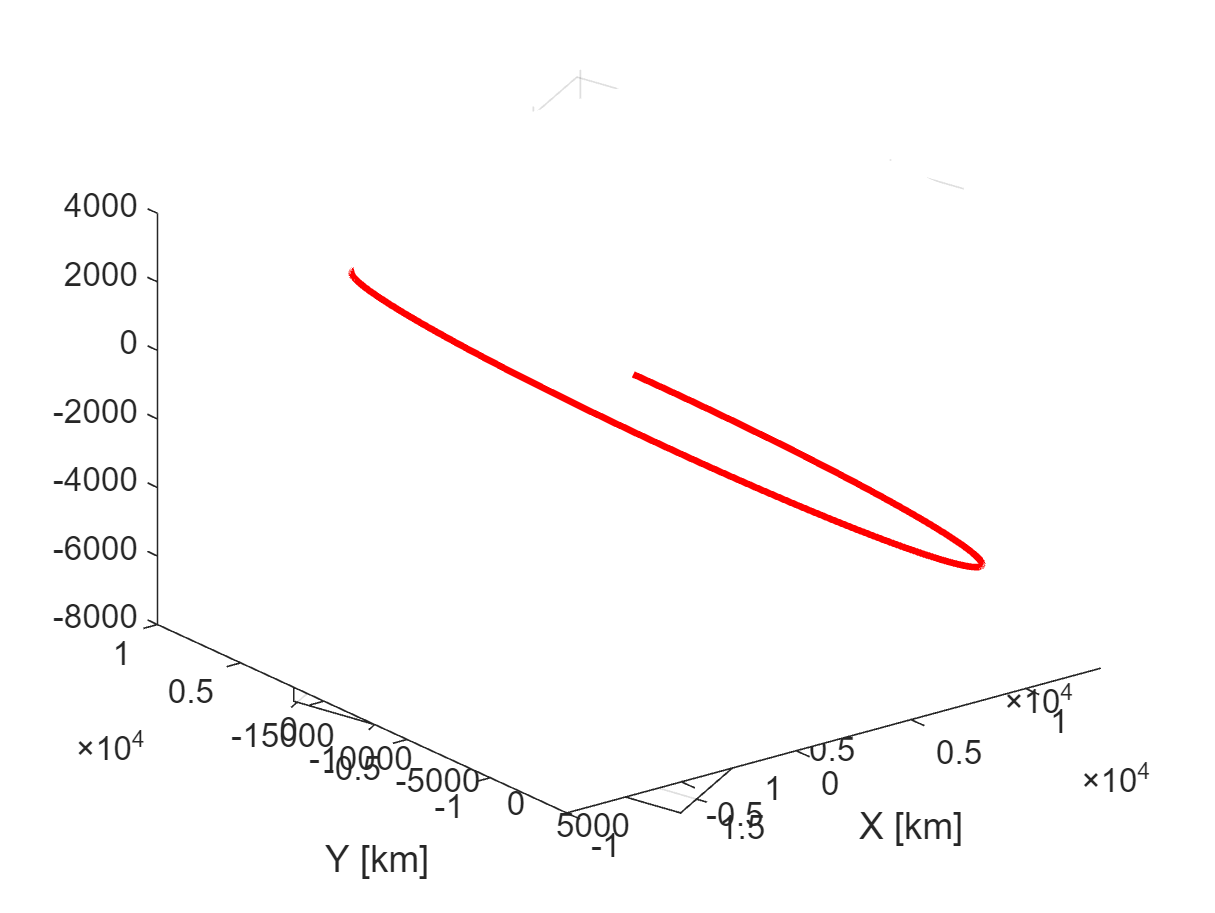

plotOrbit_new(at1, et1, inci, OMi, omi, 0, possible_theta(2), dth, mu, current_axes, comet, 'r')

% plotOrbit_new(at1, et1, incf, OMf, omf_in, possible_theta, 2*pi, dth, mu, current_axes, comet, 'r')
% plotOrbit_new(at1, et1, incf, OMf, omf_in, 0, pi, dth, mu, current_axes, comet, 'r')


Ora disegniamo la seconda ellisse di trasferimento. 

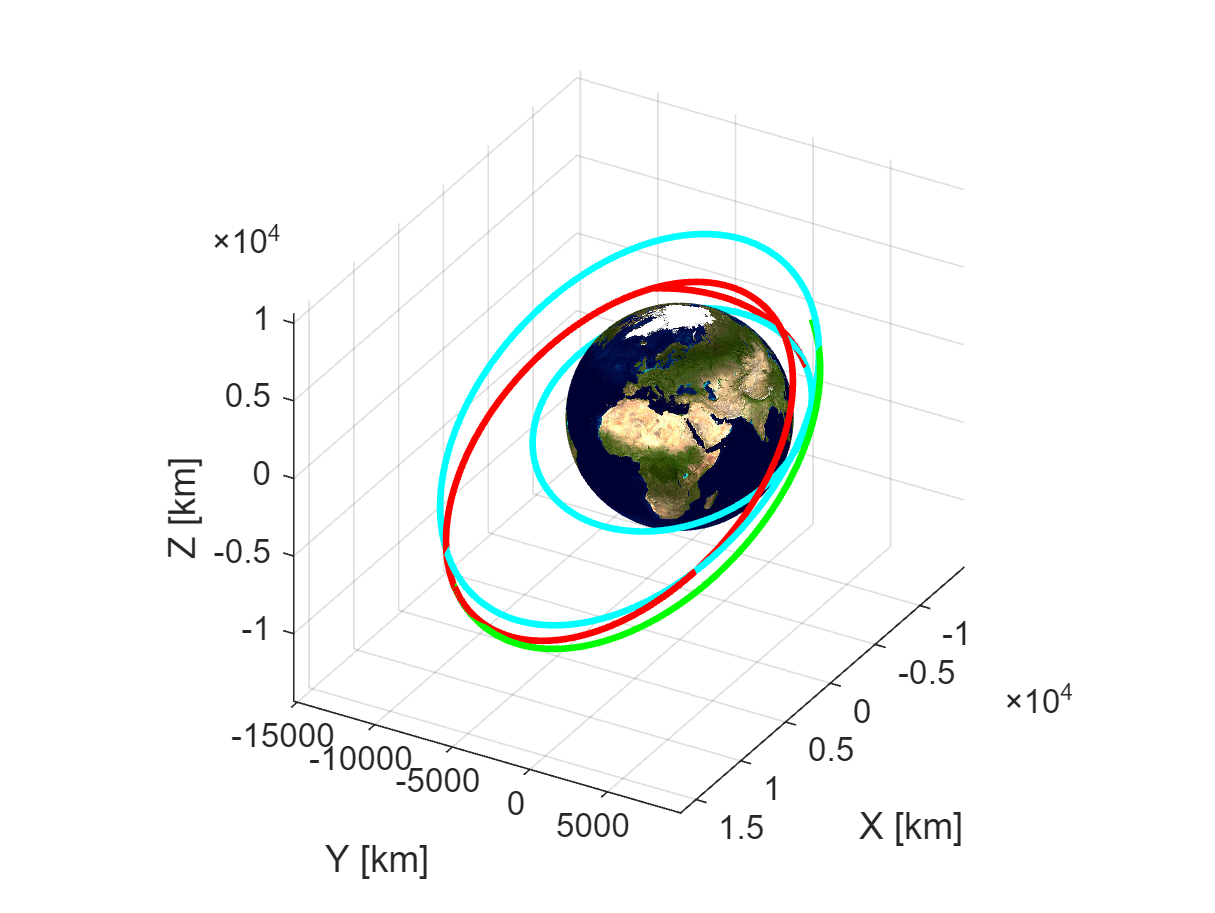

plotOrbit_new(at2, et2, incf, OMf, omf_in, pi, 2*pi, dth, mu, current_axes, comet, 'g')

### Cambio di anomalia del pericentro

L'orbita trovata è uguale all'orbita finale a meno dell'anomalia del pericentro. Troviamo i punti in cui è possibile effettuare una variazione dell'anomalia con changePericenterArg.

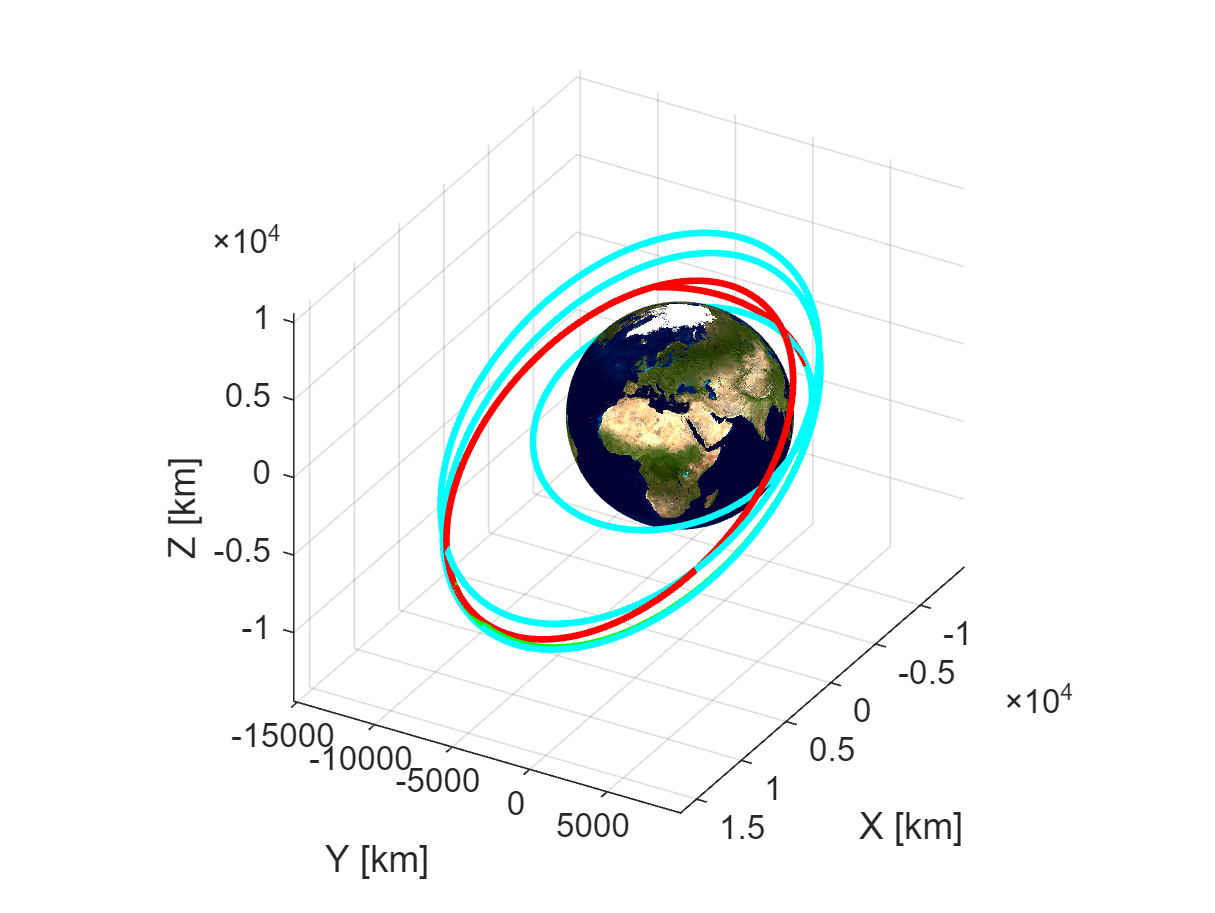

[DeltaV_perigee, thi, thf] = changePericenterArg(af, ef, omf_in, omf, mu);
plotOrbit_new(af, ef, incf, OMf, omf_in, 0, 2*pi, dth, mu, current_axes, comet)

### Colcolo DeltaV completo

Possiamo ora calcolare il DeltaV ed il Deltat completi della manovra. 

DeltaV = [DeltaV1, DeltaV2, DeltaV3, DeltaV_perigee, DeltaV_plane];
for i = 1:length(DeltaV)
    if DeltaV(i) < 0
        DeltaV(i) = - DeltaV(i)
    end
end

DeltaV =     1.0139    0.2975    0.0146    0.7355    2.3790    2.1739




TOT_DeltaV = sum(DeltaV)

TOT_DeltaV = 6.6144